# Lab2 by Cole Bardin		Section 61

## The Logistic Equation

## Part A

% Questions 1-2
clc, clear, close all
figure(1)
time_pts = -10 : 0.1 : 10;
grid on, hold on

for L = 10:-1:-10
    y_pts = logistic(time_pts, 0, L, 1);
    my_color = ((L+10.0)/20.0)*[1.0,0.0,0.0] + ((20.0-(L+10.0))/20.0)*[0.0,0.0,1.0];
    plot(time_pts, y_pts, 'Color', my_color, 'LineWidth', 3) % The standard curve.
    y_pts = logistic(time_pts, 0, L, -1);
    plot(time_pts, y_pts, 'Color', my_color, 'LineWidth', 3) % The standard curve.
end
set(gca, 'FontSize', 20)
title('Logistic Curves')
xlabel('time'); ylabel('y(t)')
axis([-10 10 -10.5 10.5])

## Part B

% Questions 3-4
clc, clear, close all
syms P(t)
r=1/2; K = 100;
DE = diff(P,t) == r*P * (1 - P/K);
sol = simplify( dsolve(DE, P(10)==50) );
p = matlabFunction(sol) % Use little p for the solution. 

p = function_handle with value:
    @(t)1.0e+2./(exp(t.*(-1.0./2.0)+5.0)+1.0)



figure(1)
t = 0:0.5:20;
curve = plot(t, p(t), 'b', 'LineWidth', 3);
set(gca, 'FontSize', 20)
title("Logistic Equation with r=1/2, K=100 million")
xlabel("Time in Days"); ylabel("P(t) in Millions");
grid on
hold on
midpoint = plot(10, 50, 'bo', 'MarkerFaceColor','y', 'MarkerSize',15);
% Question 5
r = 1/2; K = 100;
f = @(t,P) r*P * (1 - P/K);

disp("The slope at (10,50) is")

The slope at (10,50) is


disp(f(10,50))

   12.5000



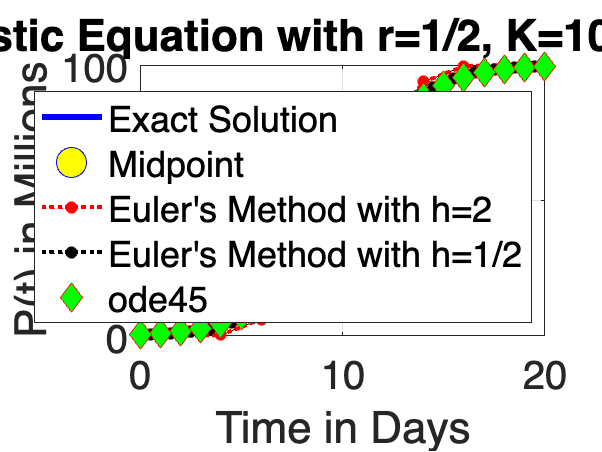


% Question 6
% Initialize the variables. Here we are using y for the population.
dt = 2; % Step size. Also called h in the notes.
tStart = 10; yStart = 50; % Population starts at P(10) = 50.
tEnd = 20; % Stopping time.
% Define time points and solution vector
t_points = tStart: dt: tEnd;
y_points = zeros(size(t_points)); % Use zeros as place holders for now.
% Initialize the solution at the initial condition.
y_points(1) = yStart;
% Implement Euler's method using a for loop.
N = length(t_points);
% forwards in time
for n = 2:N
    slope = f(t(n-1),y_points(n-1));
    y_points(n) = y_points(n-1) + slope*dt;
    tri = fill([t_points(n-1), t_points(n), t_points(n)], [y_points(n-1), y_points(n-1), y_points(n)], 'y');
    tri.FaceAlpha = 0.25;
end
euler1 = plot(t_points, y_points, 'red*:', 'LineWidth', 2); % handle = euler1
% backwards in time
dt = -dt;
t_points = tStart: dt: 0;
y_points = zeros(size(t_points)); % Use zeros as place holders for now.
% Initialize the solution at the initial condition.
y_points(1) = yStart;
% Implement Euler's method using a for loop.
N = length(t_points);
% forwards in time
for n = 2:N
    slope = f(t(n-1),y_points(n-1));
    y_points(n) = y_points(n-1) + slope*dt;
    tri = fill([t_points(n-1), t_points(n), t_points(n)], [y_points(n-1), y_points(n-1), y_points(n)], 'y');
    tri.FaceAlpha = 0.25;
end
euler2 = plot(t_points, y_points, 'red*:', 'LineWidth', 2); % handle = euler2

% Question 7
dt = 1/2;
t_points = tStart: dt: tEnd;
y_points = zeros(size(t_points)); % Use zeros as place holders for now.
% Initialize the solution at the initial condition.
y_points(1) = yStart;
% Implement Euler's method using a for loop.
N = length(t_points);
% forwards in time
for n = 2:N
    slope = f(t(n-1),y_points(n-1));
    y_points(n) = y_points(n-1) + slope*dt;
    tri = fill([t_points(n-1), t_points(n), t_points(n)], [y_points(n-1), y_points(n-1), y_points(n)], 'g');
    tri.FaceAlpha = 0.25;
end
euler3 = plot(t_points, y_points, 'k*:', 'LineWidth', 2); % handle = euler3
% backwards in time
dt = -dt;
t_points = tStart: dt: 0;
y_points = zeros(size(t_points)); % Use zeros as place holders for now.
% Initialize the solution at the initial condition.
y_points(1) = yStart;
% Implement Euler's method using a for loop.
N = length(t_points);
% forwards in time
for n = 2:N
    slope = f(t(n-1),y_points(n-1));
    y_points(n) = y_points(n-1) + slope*dt;
    tri = fill([t_points(n-1), t_points(n), t_points(n)], [y_points(n-1), y_points(n-1), y_points(n)], 'g');
    tri.FaceAlpha = 0.25;
end
euler4 = plot(t_points, y_points, 'k*:', 'LineWidth', 2); % handle = euler4

% Question 8
% forward in time
[t_out, y_out] = ode45(f, tStart: 1: tEnd, yStart);
ode45_1 = plot(t_out, y_out, 'rd', 'MarkerFaceColor','g', 'MarkerSize',10);
% backward in time
[t_out, y_out] = ode45(f, tStart: -1: 0, yStart);
ode45_2 = plot(t_out, y_out, 'rd', 'MarkerFaceColor','g', 'MarkerSize',10);

% Questions 9-10
legend([curve, midpoint, euler1, euler3, ode45_1], ["Exact Solution", "Midpoint","Euler's Method with h=2", "Euler's Method with h=1/2","ode45"], "Location", "SouthEast")